# PD por el método del LGR en Tiempo Discreto

El controlador a diseñar es de la forma $C(z)=K_p+\frac{K_d(z-1)}{Tz}=\frac{K(z-a)}{z}$

clear all, close all,  clc

#### Función de Transferencia

s= tf('s');
Ix = 0.03;
sysc = 1/Ix*(1/s^2)

sysc =
 
  33.33
  -----
   s^2
 
Continuous-time transfer function.



T = 0.01;
sysd = c2d(sysc,T)

sysd =
 
  0.001667 z + 0.001667
  ---------------------
      z^2 - 2 z + 1
 
Sample time: 0.01 seconds
Discrete-time transfer function.



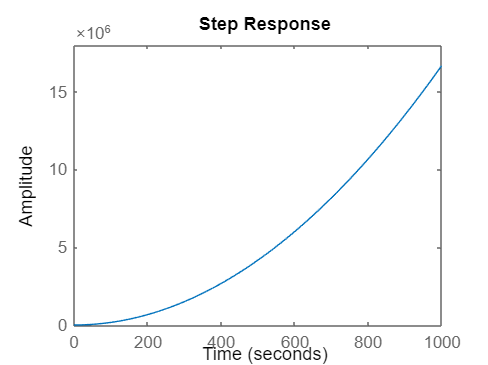


step(sysd)

[num, den] = tfdata(sysd, 'v');
roots(num)

ans = -1

roots(den)

ans =      1
     1


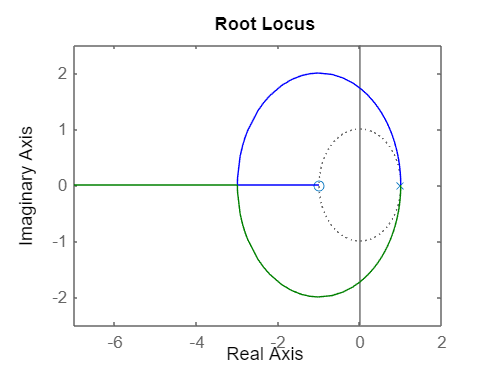

rlocus(sysd)

#### Especificaciones de diseño

Mp = 0.000001;
ts = 10;

if Mp==0
    zeta = 1
else
    zeta = sqrt( (log(Mp))^2/ (pi^2 + (log(Mp))^2) )
end

zeta = 0.9751


wn = 6.5/(ts*zeta);

número de muestras por oscilación amortiguada

ws = 2*pi/T;
wd = wn*sqrt(1-zeta^2)

wd = 0.1478

n = ws/wd

n = 4.2509e+03

#### Paso 1: Ubicación de los polos deseados

## 
$$z_d = e^{-\xi \; \frac{2\pi}{\sqrt(1-\xi^2)} \;\frac{1}{n} \; \pm \; j2\pi \frac{1}{n}} $$


zd = exp(-zeta*2*pi/(sqrt(1-zeta^2))*1/n + 1j*2*pi/n)

zd = 0.9935 + 0.0015i

#### Paso 2: Condición de Ángulo

El ángulo que puede aportar un controlador PD es:

angulosPD = 180/pi * [angle(zd+1)-angle(zd) angle(zd-1)-angle(zd)]

angulosPD =    -0.0425  167.1466


Ángulo de la función de transferencia evaluada en el polo deseado:

G_zd = evalfr(sysd, zd);     
angGz = 180/pi*angle(G_zd)   

angGz = 25.5796

Ángulo que debe aportar el controlador:

angCz = wrapTo180(180-angGz)

angCz = 154.4204

#### Paso 3: Ubicación de los Polos y Ceros a Agregar

Ángulo límite:

lim_ang_cero = 180/pi*angle(zd-1)

lim_ang_cero = 167.2313

Ángulo del cero a agregar:

ang_poloen0 = 180/pi*angle(zd)

ang_poloen0 = 0.0847

ang_cero_a = angCz + ang_poloen0

ang_cero_a = 154.5051

Ubicación del cero:

a =  real(zd) - imag(zd)/tand(ang_cero_a)

a = 0.9966

La función de transferencia del controlador hasta el momento es

Cz = zpk([a], [0], 1, T)

Cz =
 
  (z-0.9966)
  ----------
      z
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.



C_zd = evalfr(Cz, zd);
180/pi*angle(C_zd)

ans = 154.4204

#### Paso 4: Hallar la Ganancia del Controlador

Al bajar la ganancia del controlador -- Mp, ts suben

Al subir la ganancia del controlador -- Mp, ts bajan

Kc = 1/abs(C_zd*G_zd);
Cz = zpk([a], [0], Kc, T)

Cz =
 
  3.8694 (z-0.9966)
  -----------------
          z
 
Sample time: 0.01 seconds
Discrete-time zero/pole/gain model.



#### Paso 5: Verificación

180/pi*angle(evalfr(Cz*sysd, zd))

ans = 180.0000

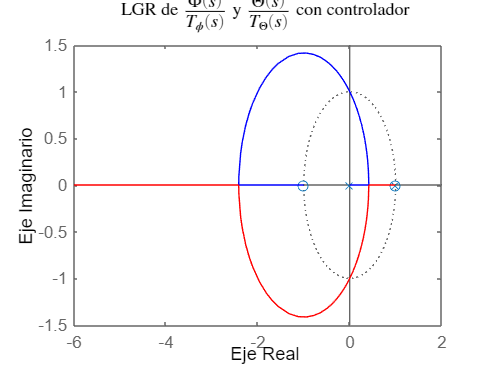

figure, 
rlocus(Cz*sysd)
title('LGR de $\frac{\Phi(s)}{T_{\phi}(s)}$ y $\frac{\Theta(s)}{T_{\Theta}(s)}$ con controlador','Interpreter','latex')
ylabel('Eje Imaginario')
xlabel('Eje Real')

se cierra el lazo con realimentación unitaria

lc = feedback(Cz*sysd,1);

se configura el escalón de amplitud 1

opt = stepDataOptions;
opt.StepAmplitude = 1;

Respuesta al escalón del sistema con controlador PD:

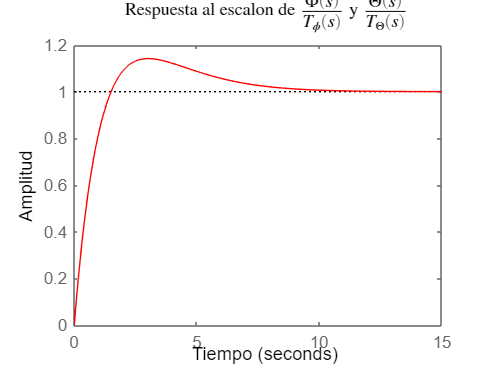

figure, 
step(lc, opt, 'r') 
title('Respuesta al escalon de $\frac{\Phi(s)}{T_{\phi}(s)}$ y $\frac{\Theta(s)}{T_{\Theta}(s)}$','Interpreter','latex')
ylabel('Amplitud')
xlabel('Tiempo')

stepinfo(lc)

ans = struct with fields:
         RiseTime: 1.1000
    TransientTime: 8.0600
     SettlingTime: 8.0600
      SettlingMin: 0.9013
      SettlingMax: 1.1418
        Overshoot: 14.1773
       Undershoot: 0
             Peak: 1.1418
         PeakTime: 3.0200


Verificación del numero de muestras por oscilación amortiguada

n= 360/(180/pi*angle(zd))

n = 4.2509e+03

## Resultados

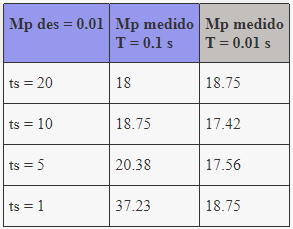

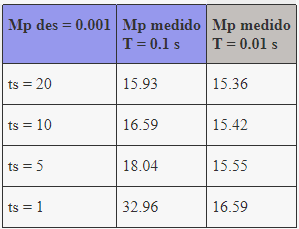

Se concluye que:


$$T = 0.01 \;s\\
t_s = 10 \; s$$
